
--- KPI Summary ---


Average total throughput: 22.74 Mbps


Average energy efficiency: 54132.75 bits/J


Average user SNR (dB): -16.66 dB


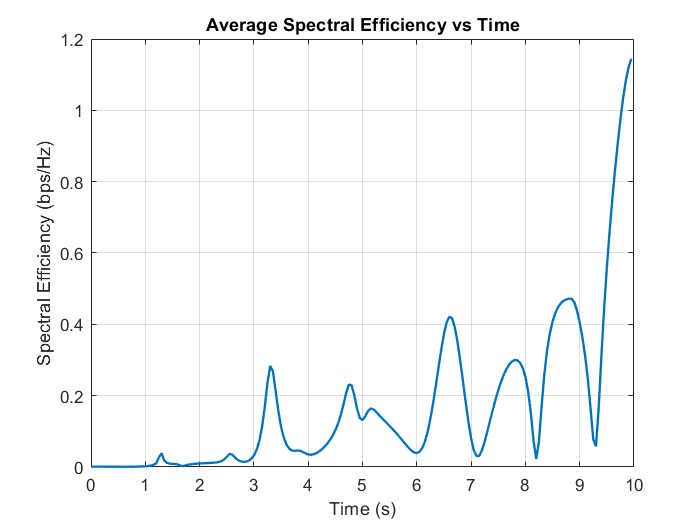

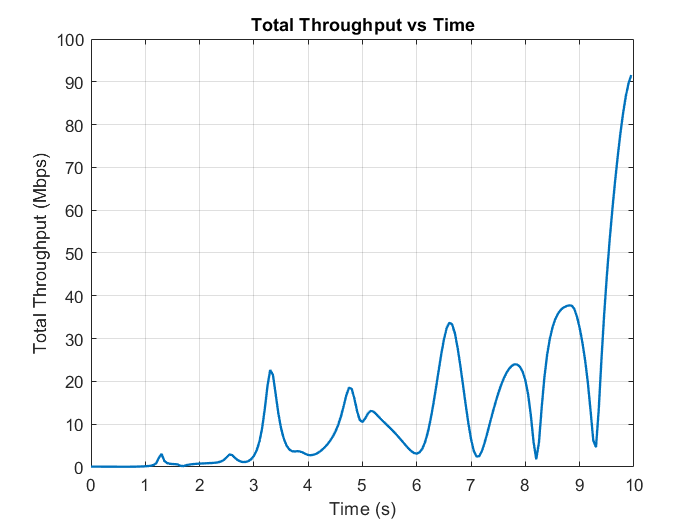

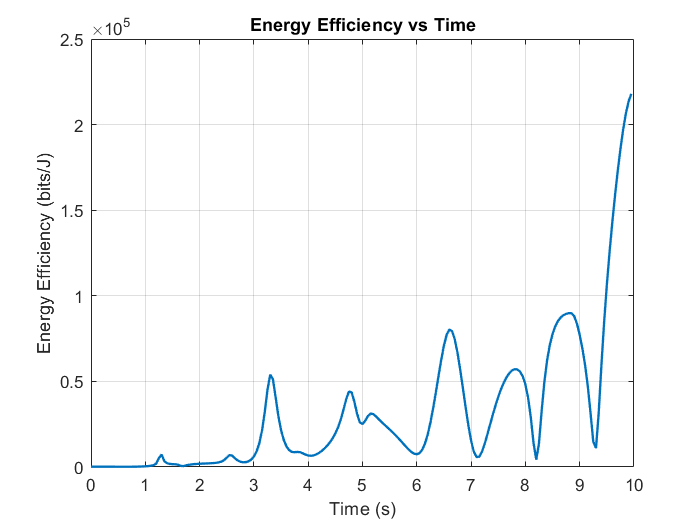

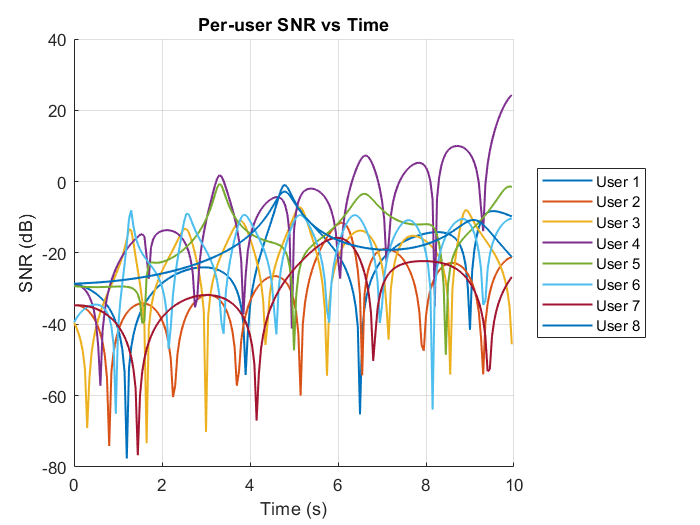

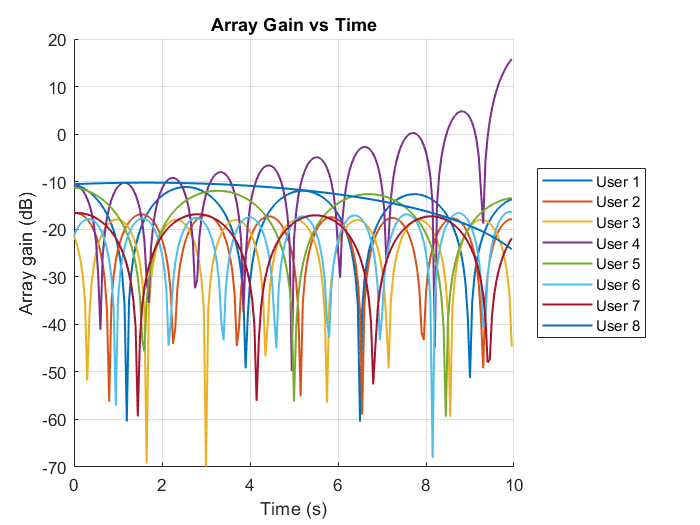

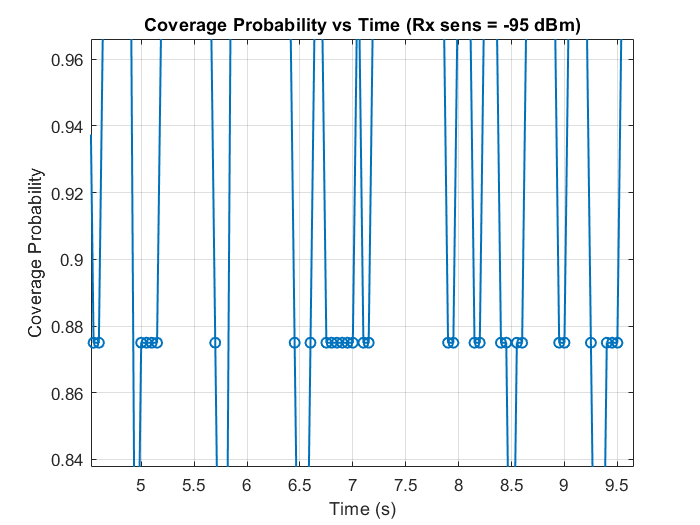


Simulation complete. Results saved to C:\Users\HP ZBOOK STUDIO G3\Downloads\Mr.areo\aas_beamforming_dynamic_results.mat


Plots saved to: C:\Users\HP ZBOOK STUDIO G3\Downloads\Mr.areo\plots


% aas_beamforming_dynamic_final.m
% Final AAS beamforming simulator (thesis-ready)
% - Dynamic user tracking (moving users)
% - Multi-user beam steering (MRT or ZF)
% - Uses optional CST radiation pattern import to shape beams
% - Calculates KPIs: Spectral Efficiency, Throughput, Energy Efficiency,
%   Beamforming Accuracy (array gain), SNR, Coverage Probability
% - Auto-saves high-res PNG plots and .mat results to specified output folder
%
% Author: Generated for user's thesis project
% Date: 2025-08-07

clear; clc; close all;


%% ----------- User settings ----------------
outFolder = 'C:\Users\HP ZBOOK STUDIO G3\Downloads\Mr.areo';
plotsFolder = fullfile(outFolder, 'plots');

% Optional CST pattern file (theta (deg), phi (deg), gain(dBi))
cst_filename = ''; % e.g. 'CST_pattern.txt'

% Save high-resolution PNGs? true/false
save_plots = true;

% Beamforming type: 'MRT' or 'ZF'
bf_method = 'MRT';

% Pathloss model: 'FSPL' or 'PL_EXPONENT'
pathloss_model = 'FSPL';

% Receiver sensitivity (dBm)
rx_sensitivity_dBm = -95;

%% ----------- Create output folders --------
if ~exist(outFolder, 'dir')
    mkdir(outFolder);
end
if ~exist(plotsFolder, 'dir')
    mkdir(plotsFolder);
end

%% ----------- Simulation parameters --------
fc = 3.5e9;                         
c = physconst('LightSpeed');        
lambda = c / fc;

numElements = 64;                   
d = lambda/2;                       
elementPos = ((0:numElements-1) - (numElements-1)/2) * d;

T = 200;                            
dt = 0.05;                          
time = (0:T-1) * dt;

K = 8;                              
user_az0 = linspace(-60,60,K);      
rng(0);
user_ang_vel = (rand(1,K)-0.5) * 2; 

Pt_dBm = 30; Pt = 10^((Pt_dBm-30)/10); 
bandwidth = 10e6;                    
kB = 1.380649e-23; T0 = 290; NF_dB = 5;
noise_power = kB * T0 * bandwidth * 10^(NF_dB/10); 
noise_power_dBm = 10*log10(kB*T0*bandwidth*1000) + NF_dB;

dist_m = 200 * ones(1,K);
pl_exponent = 3;
reference_dist = 1;

%% ----------- Load CST pattern -------------
use_cst = false;
if ~isempty(cst_filename) && exist(cst_filename,'file')
    try
        txt = readmatrix(cst_filename);
        theta_cst = txt(:,1);
        gain_cst_dBi = txt(:,3);
        gain_lookup = @(theta) interp1(theta_cst, gain_cst_dBi, theta, 'linear', 'extrap');
        use_cst = true;
        fprintf('Loaded CST pattern from %s\n', cst_filename);
    catch
        warning('Could not read CST file. Continuing with ideal element gain.');
    end
end

%% ----------- Pre-allocations --------------
user_az = zeros(K, T);
for k = 1:K, user_az(k,1) = user_az0(k); end

SNR_dB_time = zeros(K, T);
array_gain_dB_time = zeros(K, T);
throughput_time = zeros(K, T);
coverage_prob_time = zeros(1,T);

steer_vec = @(theta_deg) exp(-1j * 2*pi / lambda * (sin(deg2rad(theta_deg)) .* elementPos)).';

%% ----------- Main simulation loop ---------
for ti = 1:T
    if ti > 1
        user_az(:,ti) = user_az(:,ti-1) + (user_ang_vel.' * dt);
    end
    
    SV = zeros(numElements, K);
    for k = 1:K
        SV(:,k) = steer_vec(user_az(k,ti));
        SV(:,k) = SV(:,k) / norm(SV(:,k)) * sqrt(numElements);
    end
    
    W = zeros(numElements, K);
    switch upper(bf_method)
        case 'MRT'
            for k = 1:K
                w = conj(SV(:,k));
                w = w / norm(w);
                W(:,k) = w;
            end
        case 'ZF'
            W_all = pinv(SV).';
            for k = 1:K
                w = W_all(:,k);
                w = w / norm(w);
                W(:,k) = w;
            end
    end
    
    num_covered = 0;
    for k = 1:K
        sv_k = SV(:,k);
        w_k = W(:,k);
        
        gain_lin = abs(w_k' * sv_k)^2;
        array_gain_dB_time(k,ti) = 10*log10(gain_lin + 1e-12);
        
        interf_lin = 0;
        for j = 1:K
            if j ~= k
                interf_lin = interf_lin + abs(W(:,j)' * sv_k)^2;
            end
        end
        
        switch upper(pathloss_model)
            case 'FSPL'
                FSPL_dB = 20*log10(4*pi*dist_m(k)/lambda);
                PL_lin = 10^(FSPL_dB/10);
            case 'PL_EXPONENT'
                PL_lin = (dist_m(k)/reference_dist)^pl_exponent;
        end
        
        if use_cst
            element_gain_dBi = gain_lookup(user_az(k,ti)); 
            element_gain_lin = 10^(element_gain_dBi/10);
        else
            element_gain_lin = 1;
        end
        
        Pr_desired = Pt * gain_lin * element_gain_lin / PL_lin;
        Pr_interf = Pt * interf_lin * element_gain_lin / PL_lin;
        
        snr_lin = Pr_desired / (noise_power + Pr_interf);
        SNR_dB_time(k,ti) = 10*log10(snr_lin + 1e-12);
        
        se = log2(1 + snr_lin); 
        throughput_time(k,ti) = se * bandwidth;
        
        Pr_dBm = 10*log10(Pr_desired*1000 + 1e-30);
        if Pr_dBm >= rx_sensitivity_dBm
            num_covered = num_covered + 1;
        end
    end
    coverage_prob_time(ti) = num_covered / K;
end

%% ----------- KPI aggregation --------------
total_throughput_time = sum(throughput_time,1); 
p_static_watts = 100; p_per_element_watts = 5;
p_total_aas = p_static_watts + numElements * p_per_element_watts;
EE_time = total_throughput_time ./ p_total_aas; 

steady_idx = round(T/2):T;
avg_throughput = mean(total_throughput_time(steady_idx));
avg_EE = mean(EE_time(steady_idx));
avg_SNR_dB = mean(mean(SNR_dB_time(:, steady_idx),2));

fprintf('\n--- KPI Summary ---\n');
fprintf('Average total throughput: %.2f Mbps\n', avg_throughput/1e6);
fprintf('Average energy efficiency: %.2f bits/J\n', avg_EE);
fprintf('Average user SNR (dB): %.2f dB\n', avg_SNR_dB);

%% ----------- Plots ------------------------
SE_time = sum(throughput_time,1) / (bandwidth * K);

fig1 = figure; plot(time, SE_time,'LineWidth',1.4); grid on;
xlabel('Time (s)'); ylabel('Spectral Efficiency (bps/Hz)');
title('Average Spectral Efficiency vs Time');
save_png(fig1, 'SpectralEfficiency_vs_Time', save_plots, plotsFolder);

fig2 = figure; plot(time, total_throughput_time/1e6,'LineWidth',1.4); grid on;
xlabel('Time (s)'); ylabel('Total Throughput (Mbps)');
title('Total Throughput vs Time');
save_png(fig2, 'TotalThroughput_vs_Time', save_plots, plotsFolder);

fig3 = figure; plot(time, EE_time,'LineWidth',1.4); grid on;
xlabel('Time (s)'); ylabel('Energy Efficiency (bits/J)');
title('Energy Efficiency vs Time');
save_png(fig3, 'EnergyEfficiency_vs_Time', save_plots, plotsFolder);

fig4 = figure; hold on;
for k = 1:K, plot(time, SNR_dB_time(k,:),'LineWidth',1.2); end
grid on; xlabel('Time (s)'); ylabel('SNR (dB)');
title('Per-user SNR vs Time');
legend(arrayfun(@(k) sprintf('User %d',k),1:K,'UniformOutput',false),'Location','eastoutside');
save_png(fig4, 'PerUserSNR_vs_Time', save_plots, plotsFolder);

fig5 = figure; hold on;
for k = 1:K, plot(time, array_gain_dB_time(k,:),'LineWidth',1.2); end
grid on; xlabel('Time (s)'); ylabel('Array gain (dB)');
title('Array Gain vs Time');
legend(arrayfun(@(k) sprintf('User %d',k),1:K,'UniformOutput',false),'Location','eastoutside');
save_png(fig5, 'ArrayGain_vs_Time', save_plots, plotsFolder);

fig6 = figure; plot(time, coverage_prob_time,'-o','LineWidth',1.2); grid on;
xlabel('Time (s)'); ylabel('Coverage Probability');
title(sprintf('Coverage Probability vs Time (Rx sens = %d dBm)', rx_sensitivity_dBm));
save_png(fig6, 'CoverageProbability_vs_Time', save_plots, plotsFolder);

%% ----------- Save results -----------------
results_file = fullfile(outFolder, 'aas_beamforming_dynamic_results.mat');
save(results_file, 'user_az', 'SNR_dB_time', 'array_gain_dB_time', ...
    'throughput_time', 'total_throughput_time', 'EE_time', 'time', ...
    'elementPos', 'coverage_prob_time');

fprintf('\nSimulation complete. Results saved to %s\n', results_file);
if save_plots
    fprintf('Plots saved to: %s\n', plotsFolder);
end

%% ----------- Local function ----------------

function save_png(fig, name, save_plots, plotsFolder)
    if save_plots
        set(0,'CurrentFigure',fig);
        print(fig, fullfile(plotsFolder, [name '.png']), '-dpng', '-r300');
    end
end
